clc;clear;close all;

定义符号

syms g mu xi__1 xi__2 f
R(g,mu,xi__1,xi__2,f) = sqrt(((-g ^ 6 + (1 + (-4 * mu * xi__2 ^ 2 - 4 * xi__2 ^ 2 + mu + 2) * f ^ 2) * g ^ 4 ...
    - ((mu + 1) * f ^ 2 - 4 * xi__2 ^ 2 + 2) * f ^ 2 * g ^ 2 + f ^ 4) ^ 2) / ((g ^ 8) ...
    + (0.4e1 * (mu + 1) * ((mu * xi__2 ^ 2) ...
    + (xi__2 ^ 2) - 0.1e1 / 0.2e1) * (f ^ 2) ...
    + (8 * f * mu * xi__1 * xi__2) ...
    + (4 * xi__1 ^ 2) - 0.2e1) * (g ^ 6) ...
    + ((1 + (mu + 1) ^ 2 * f ^ 4 ...
    + (16 * xi__1 ^ 2 * xi__2 ^ 2 - 8 * mu * xi__2 ^ 2 - 8 * xi__1 ^ 2 ...
    - 8 * xi__2 ^ 2 + 2 * mu + 4) * f ^ 2) * g ^ 4) ...
    - (2 * (f ^ 2 * (-2 * xi__1 ^ 2 + mu + 1) - 2 * xi__2 ^ 2 + 1) * f ^ 2 * g ^ 2) ...
    + (f ^ 4)) ^ 2 + 0.4e1 * (((xi__2 * f * mu + xi__1) * g ^ 4) + 0.4e1 * ((xi__2 ^ 2) ...
    - 0.1e1 / 0.2e1) * xi__1 * (f ^ 2) * (g ^ 2) ...
    + (f ^ 4 * xi__1)) ^ 2 * (g ^ 2) / ((g ^ 8) + ...
    (0.4e1 * (mu + 1) * (-0.1e1 / 0.2e1 + ((mu + 1) * xi__2 ^ 2)) * (f ^ 2) ...
    + (8 * f * mu * xi__1 * xi__2) + (4 * xi__1 ^ 2) - 0.2e1) * (g ^ 6) ...
    + ((1 + (mu + 1) ^ 2 * f ^ 4 + ((16 * xi__1 ^ 2 - 8 * mu - 8) * xi__2 ^ 2 ...
    - 8 * xi__1 ^ 2 + 2 * mu + 4) * f ^ 2) * g ^ 4) ...
    - (2 * (f ^ 2 * (-2 * xi__1 ^ 2 + mu + 1) - 2 * xi__2 ^ 2 + 1) * f ^ 2 * g ^ 2) ...
    + (f ^ 4)) ^ 2);




单个点绘图

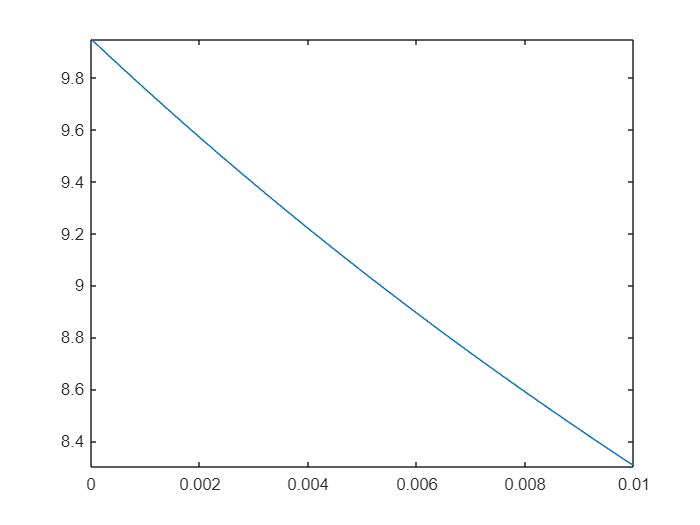

fplot(R(1,0.01,xi__1,0.05,1),[0,0.01])

循环绘图

% tt=0.5:0.1:1.5
% for k1 = 1:length(tt)
%     fplot(R(tt,0.01,xi__1,0.05,1),[0,0.01])
%     hold on
% end

给结构阻尼求导为0

clc;clear;close all
syms g mu xi__2 f
xi__1 = -f * g ^ 4 * mu * xi__2 / (4 * f ^ 2 * g ^ 2 * xi__2 ^ 2 + f ^ 4 - 2 * f ^ 2 * g ^ 2 + g ^ 4);
